# Simulation of different cases

## General case example:

### Orbit, Time and Attitude parameters

In this section of the code, the following parameters are set: Orbit (with the 6 orbital parameters, RAAN defines the beta angle), the date of the simulation and what is the pointing of the satellite. the pointing mode can be set as:

- MODE = 1: "orbital" Reference quaternion is aligned with ORF. 

- MODE = 2: "sun-aero" Reference quaternion is such that x is aligned with velocity and z is aligned as best as possible with the sun direction to maximize the power generation 

- MODE = 3: "sun pointing" Reference quaternion is such that z is aligned with with the sun direction to maximize the power generation and x is aligned as best as possible with the velocity direction. 

- MODE = 4: "aero-drag" Reference quaternion is similar than in Case 1, but rotated 90° along the y axis, therefore, the reference quaternion is an attitude for 

- %maximizing the drag surface. 

- MODE = 5: "retrogade firing" Reference quaternion is similar than in Case 1, but rotated 180° along the z axis, therefore, the reference quaternion is an attitude for retrograde propulsion. 

- MODE = 6: Reference quaternion is static [1 0 0 0], but this time is the only case  where the state of the B-dot is enabled (1). 

- MODE = 7: Reference quaternion is a custom quaternion that has to be defined by the user as an input to the mission block. 

- MODE = 8: Reference quaternion is similar to case 3, but with the degree of freedom it tries to align to the nadir direction to maximize the drag surface.

- MODE = 9: Same as #2, but there is a rotation of 45 degrees to maximize power generation (panels +X, +Y).

- MODE = 10: Same as #3, but there is a rotation of 45 degrees to maximize power generation (panels +X, +Y).

- MODE = 11: SLERP: a fraction "t" represents the linear interpolation between modes 9 an 10.

The conditions were set as follow:

clear all
close all

%Orbit: Initialisation of Keplerian parameters
orbit.a = 6671e3;       %semimajor axis [m] ~293km
orbit.e = 0.001;        %eccentricity
orbit.i = 51.6;         %inclination [degrees]
orbit.O = 60;           %Right ascension of the right ascending node [degrees] 
orbit.o = 90;           %Argument of the perigee [degrees]                     
orbit.nu = 0;           %True anomaly [degrees]

%Initialisation of date
date.year=2026;
date.month=3;
date.day=21;
date.hour=0;
date.minutes=0;
date.seconds=0;

%POINTING MODE
MODE = 9;   %"sun-aero" with side panels 45deg.  pointing mode
att.t = 0;  %for mode 11
att.angle_roll = pi/4;  %Rotated angle in roll for MODE 9, 10, 11

### Power Generation

In this section is where the power generation conditions are set.

%Power Generation
SP.Pcell = 2.32*0.436;    % Peak power generated by a cell, no conversion efficiency
SP.PsaX = 7 * SP.Pcell;   %Peak power generation +Z side[W] 7 solar cells
SP.Psa_X = 0 * SP.Pcell;  %Peak power generation -Z side[W] 0 solar cells
SP.PsaY = 7 * SP.Pcell;   %Peak power generation +Z side[W] 7 solar cells
SP.Psa_Y = 7 * SP.Pcell;  %Peak power generation -Z side[W] 7 solar cells

### Battery Configuration

The battery configuration is 1S 4P

Bat.Cbat=2.6;           %Cell capacity in [Ah]
Bat.Nbs=1;
Bat.Nbp=4;
Bat.C=Bat.Cbat*Bat.Nbp*3600;    %Battery Capacity for all parallel arrays [Ampere*sec]
%Power distribution efficiencies
Bat.eff_iBat=0.9;       %efficiency from Battery to load
Bat.eff_i1=0.9;         %efficiency PDU CH not regulated
Bat.eff_i2=0.9;         %efficiency PDU CH 3.3V
%Battery
Bat.DOD_0=0.1;          %initial DOD from 0 to 1
Batt.C1 = 7240;         %internal capacitance model Battery [F]
Batt.R2 = 0.01968;      %internal charging resistance model battery [Ohm]
Batt.SoC_0=1-Bat.DOD_0; %Initial SoC
%Charge/Discharge logic
Bat.I_BD_max= 5.2*Bat.Nbp;     %Maximum discharge current [A] approx. 2C rate
Bat.I_BC_max= -2.6*Bat.Nbp;     %Maximum charge current [A] approx. 1C rate

### Loads

Listed below all the loads

%EPS
EPS.eff_MPPT = 0.89;     %efficiency MPPT conversion
EPS.P_eps = 0.11*2;      %internal power consumption 2xEPS [W]
EPS.margin = 0.1;

%Subsystem Loads
%OBC
OBC.power=0.015;     %Required power OBC [W]
OBC.margin=0.1;      %margin OBC: 10%
OBC.eff=0.9;         %efficiency CH OBC


%Thruster required power
OCS.n=2;
OCS.m=2;
OCS.pt_idle=0.35;       %0.35W according to datasheet
OCS.pt_heat=3-0.35;     %3W heating for 10sec
OCS.pt_peak=12.5-0.35;  %Required power Thruster [W]
OCS.t0=180*60;          %Time wait before first use of the Thruster;
OCS.t_n=300*60;         %time waiting between 2 firings, 'recharging' [seconds], 350 minutes
OCS.t_m=3.8*60*60;      %time waiting between 2 sets of firings, [seconds], 3.8*2+t_n+t0 hours
OCS.d_h= 10;            %time heating thruster: in [s]
OCS.d_t = 6;            %seconds, total time of thrust (without heating of the thruster)
[OCS.t_thr,OCS.p_thr]=calc_thrust_power(OCS.pt_peak,OCS.pt_heat,OCS.pt_idle,...
    OCS.d_h, OCS.d_t, OCS.n, OCS.m, OCS.t0, OCS.t_n, OCS.t_m);
OCS.eff=0.95;
OCS.margin=0.05;        %Margin Thruster consumption: 10%

%ADCS
%P_ADC=0.463;          %power consumption by sensors and eq. at 3.3V
%P_ADC=2.063;          %power consumption by sensors and eq. at 3.3V

ADCS.powerelec = 0.326;     %power consumption by sensors and eq. at 3.3V
ADCS.effpowerelec = 0.9;
ADCS.powerPanel = 0.048;    %idle power consumption from 3 panels
ADCS.effPanel = 0.9;
ADCS.power1 = ADCS.powerelec/ADCS.effpowerelec + ADCS.powerPanel/ADCS.effPanel;
%ADCS.eff1 = 0.9;           %Efficiency CH ADCS 1 3.3V
ADCS.margin1 = 0.1;

%ADCS.powerRWs = 1.5;        %Reaction wheel power consumption average?
ADCS.powerRWs = 0.7;        %Reaction wheel power consumption average
ADCS.effRW = 0.9;
ADCS.marginRWs = 0.2;

%ADCS.powerMTQ = 0.33;      %Reaction wheel power consmuption average?
ADCS.powerMTQ = 0.13;       %Reaction wheel power consmuption average?
ADCS.effMTQ = 0.90;
ADCS.marginMTQ = 0.1;

%GNSS
GPS.power = 0.157;      %Required power GPS [W]
GPS.eff = 0.95;         %efficiency CH 
GPS.margin = 0.1;       %margin GPS power consumption 10%


%COM UHF subsystem
UHF.n = 5;
UHF.m = 2;
UHF.pc_idle = 0.22;       %Power comm idle: 32mW, only rx: 0.22W
UHF.pc_half = 0.22;       %no heating
UHF.pc_full = 3.055;      %Required power Tx+Rx [W]
UHF.t0_c = 150*60;        %Time wait before first use of the UHF TRx;
UHF.t_n = 90*60;          %time waiting between 2 transmission [seconds], 90 minutes
UHF.t_m = 16*60*60;       %time waiting between 2 transmissions [seconds], 16 hours
UHF.d_h = 1;              %time heating thruster: in [s]
UHF.d_f = 6*60;           %seconds, total time of thrust (without heating of the thruster)
[UHF.t_tx_UHF,UHF.p_tx_UHF]=calc_comm_power(UHF.pc_idle,UHF.pc_half,UHF.pc_full, ...
    UHF.d_h, UHF.d_f, UHF.n, UHF.m, UHF.t0_c, UHF.t_n, UHF.t_m);
[UHF.sorted_t, UHF.idx] = sort(UHF.t_tx_UHF);
UHF.sorted_p = UHF.p_tx_UHF(UHF.idx);
[UHF.unique_t, ia, ~] = unique(UHF.sorted_t, 'stable');
UHF.unique_p = UHF.sorted_p(ia);
UHF.t_tx_UHF = UHF.unique_t;
UHF.p_tx_UHF = UHF.unique_p;
UHF.eff = 0.95;         %efficiency CH COM
UHF.margin = 0.1;       %Margin UHF power 10%


% PAYLOAD
%processor + antenna on side panel -X
PL.n = 5;
PL.m = 2;
PL.pp_idle = 0.02;       %Interface board [W]
PL.pp_half = 0.02;       %no heating
%PL.pp_full = 30.59;      %Required power Tx+Rx [W]
PL.pp_full = 38.40;      %Required power Tx+Rx [W]
PL.t0_p = 151*60;        %Time wait before first use of the Payload;
PL.t_n = 90*60;          %time waiting between 2 transmission [seconds], 90 minutes
PL.t_m = 20*60*60;       %time waiting between 2 transmissions [seconds], 20 hours
PL.d_h = 1;              %time heating thruster: in [s]
PL.d_f = 5.5*60;         %seconds, total time of trx (without heatingr)
[PL.t_tx_S,PL.p_tx_S]=calc_comm_power(PL.pp_idle,PL.pp_half,PL.pp_full,... 
    PL.d_h, PL.d_f, PL.n, PL.m, PL.t0_p, PL.t_n, PL.t_m);

[PL.sorted_t, PL.idx] = sort(PL.t_tx_S);
PL.sorted_p = PL.p_tx_S(PL.idx);
[PL.unique_t, ia, ~] = unique(PL.sorted_t, 'stable');
PL.unique_p = PL.sorted_p(ia);
PL.t_tx_S=PL.unique_t;
PL.p_tx_S=PL.unique_p;
PL.eff=0.95;            %efficiency CH COM
PL.margin=0.05;          %Margin power consumption 10%


%FIPEX
FIPEX.P_op_fi=4.2;        %Required power heater/fipex [W], 
FIPEX.P_heat_fi=11;
FIPEX.t0_Fi=12*90*60;     %approx 12 orbits before start in [seconds]
FIPEX.tON_Fi=90*60;       %Duration of Fipex payload ON: 1 orbit in [seconds]
FIPEX.tend_Fi=24*60*60;   %end of cycle, 1 day, 1 activation per day
FIPEX.P_idle_Fi=0;
FIPEX.p_Fi=[FIPEX.P_idle_Fi   FIPEX.P_idle_Fi   FIPEX.P_heat_fi   FIPEX.P_heat_fi  FIPEX.P_op_fi    FIPEX.P_op_fi       FIPEX.P_idle_Fi          FIPEX.P_idle_Fi];
FIPEX.t_Fi=[0           FIPEX.t0_Fi-21    FIPEX.t0_Fi-20    FIPEX.t0_Fi-1    FIPEX.t0_Fi      FIPEX.t0_Fi+FIPEX.tON_Fi  FIPEX.t0_Fi+FIPEX.tON_Fi+1    FIPEX.tend_Fi];
FIPEX.eff = 0.95;
FIPEX.margin = 0.1;

Listed below which loads are active

EN.Thr=1;           %Thruster Enabled=1, disabled=0
EN.OBC=1;           %OBC Enabled=1, disabled=0
EN.ADCS1=1;         %ADCS 3.3V Enabled=1, disabled=0
EN.RW=1;
EN.MTQ=1;
EN.UHF=1;           %TRx UHF enabled=1
EN.S=1;             %Payload Ka-band enabled=1
EN.GPS=1;           %GPS Enabled=1, disabled=0
EN.heat=1;          %Fipex Enabled=1, disabled=0

### Some plots

OBC, EPS, ADCS sensors, Panels, GPS, Interface Board are constant, 5 are time variable:

- Thruster

- ADCS RW & MTQ

- UHF

- Payload Ka band (Processor + Antenna Panel)

- FIPEX

#### a) Thruster

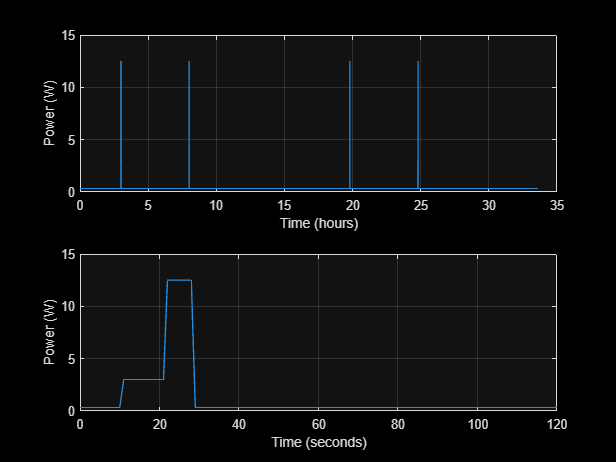

close all
figure(1)
set(gcf,'color','black');
subplot(2,1,1)
    plot(OCS.t_thr/3600,OCS.p_thr)
    hold on
    xlabel('Time (hours)')
    ylabel('Power (W)')
    grid on
    
subplot(2,1,2)
    plot(OCS.t_thr-OCS.t0+10,OCS.p_thr)
    hold on
    xlabel('Time (seconds)')
    ylabel('Power (W)')
    xlim([0 120])
    grid on

#### c) UHF Transmitter

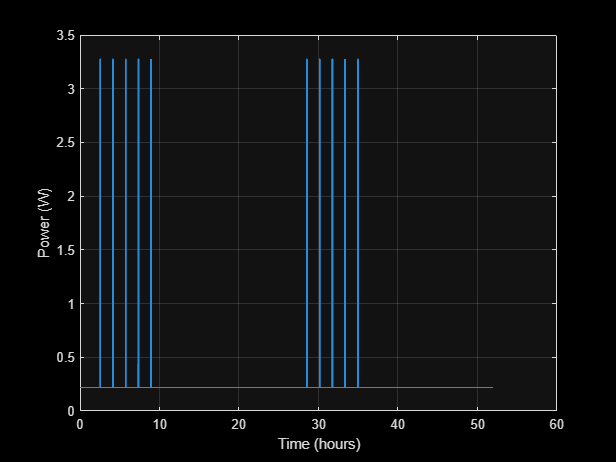

figure(3)
set(gcf,'color','black');
    plot(UHF.t_tx_UHF/3600,UHF.p_tx_UHF)
    hold on
    grid on
    xlabel('Time (hours)')
    ylabel('Power (W)')
    ylim([0 3.5])

#### d) Payload Ka band

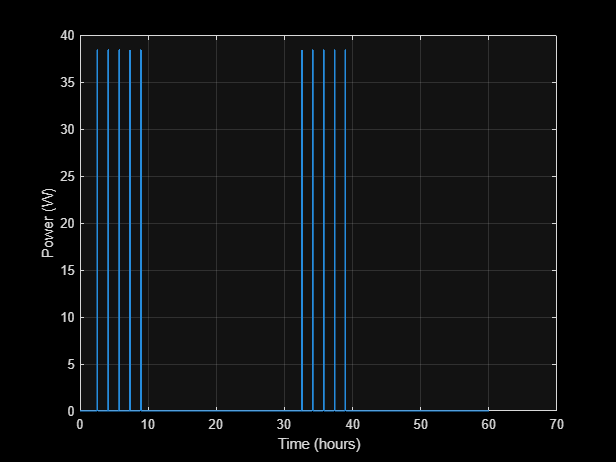

figure(4)
%set(gcf,'color','white');
%set(gcf,'InvertHardcopy','off'),
set(gcf,'color','black');
    plot(PL.t_tx_S/3600,PL.p_tx_S)
    %set(gca,'color','white');
    hold on, grid on
    xlabel('Time (hours)')
    ylabel('Power (W)')

    %ylim([0 35])

#### e) FIPEX

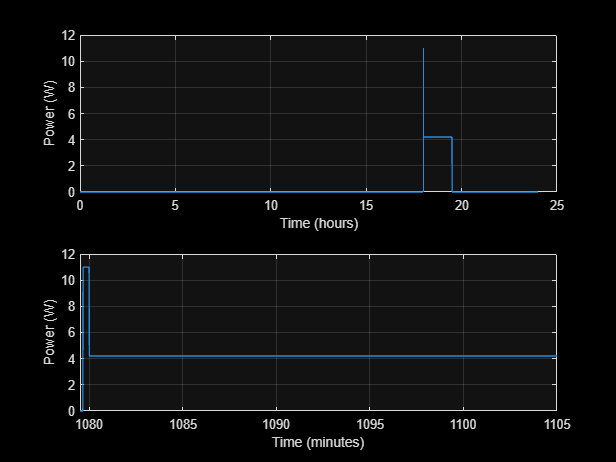

figure(5)
set(gcf,'color','black');
    subplot(2,1,1)
    plot(FIPEX.t_Fi/3600,FIPEX.p_Fi)
    hold on, grid on
    xlabel('Time (hours)')
    ylabel('Power (W)')
    ylim([0 12])
    subplot(2,1,2)
    plot(FIPEX.t_Fi/60,FIPEX.p_Fi)
    xlim([(FIPEX.t0_Fi-30)/60 (FIPEX.t0_Fi+1500)/60])
    ylim([0 12])
    hold on, grid on
    xlabel('Time (minutes)')
    ylabel('Power (W)')

### Simulations

First set up the time:

%Duration of the simulation
Torb=2*pi*sqrt((orbit.a/1000)^3/(3.986004418E5)); %Orbit duration
N_orbits = 16; %15 = 1 day
tsimulation = N_orbits*Torb;
delta_t = 1; %simulation time step (seconds)
TimeStep = delta_t; %just for some simulink block

The simulations are performed:

Power=sim('EPS_orbit_v3b');

E=sim('EPS_sim_test_v7a');

Found algebraic loop containing: 
EPS_sim_test_v7a/Battery Model/IC
EPS_sim_test_v7a/LOADS/Divide2
EPS_sim_test_v7a/LOADS/Divide
EPS_sim_test_v7a/LOADS/Manual Switch (discontinuity)
EPS_sim_test_v7a/LOADS/Divide3
EPS_sim_test_v7a/LOADS/Manual Switch1 (discontinuity)
EPS_sim_test_v7a/LOADS/Divide6


Processing data:

timesec = E.tout;
time=timesec/60;  %to plot in minutes
DOD = getdatasamples(E.DOD,(1:length(time)));
Vbat = getdatasamples(E.Vbat,(1:length(time)));
Ibat = getdatasamples(E.Ibat,(1:length(time)));
SOC = 100*(1 - DOD);
Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
beta = getdatasamples(Power.beta,(1:length(time)));
Ploads = getdatasamples(E.LOAD,(1:length(time)));
Ploadsingle = getdatasamples(E.LOADS,(1:length(time)));

%get charge and discharge currents
ibc=zeros(length(time),1);
ibd=zeros(length(time),1);
for i=1:length(time)
    if Ibat(i)>0
        ibc(i,1)=0;
        ibd(i,1)=Ibat(i);
    end
    if Ibat(i)<0
        ibc(i,1)=-Ibat(i);
        ibd(i,1)=0;
    end
end

%Mean values
MEAN.mean_power_loads_OCS=mean(Ploadsingle(:,1));
MEAN.mean_power_loads_ADCS=mean(Ploadsingle(:,2));
MEAN.mean_power_loads_UHF=mean(Ploadsingle(:,3));
MEAN.mean_power_loads_OBC=mean(Ploadsingle(:,4));
MEAN.mean_power_loads_GPS=mean(Ploadsingle(:,5));
MEAN.mean_power_loads_FIPEX=mean(Ploadsingle(:,6));
MEAN.mean_power_loads_Ka=mean(Ploadsingle(:,7));

#### Plots

The plots show the following:

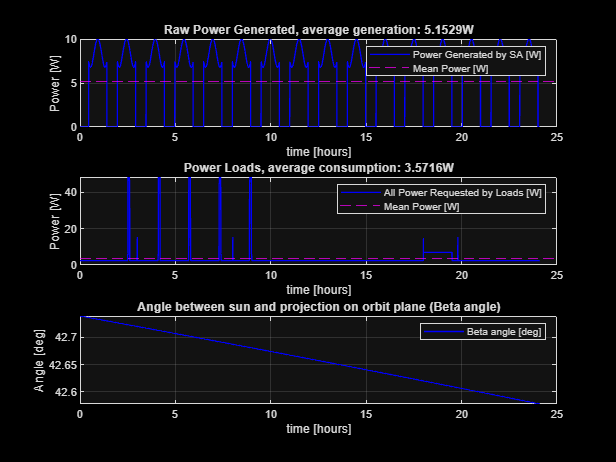

close all
time=timesec/3600;  %to plot in minutes
mean_power_collected=mean(Pcollected);
mean_power_loads=mean(Ploads);
figure(7)
%set(gcf,'color','w');
%set(gca,'color','w');
%set(gcf,'InvertHardcopy','off'),
set(gcf,'color','black');
    subplot(3,1,1)
        plot(time,Pcollected,'b','LineWidth',1)
        hold on;
        yline(mean_power_collected,'m--')
        legend('Power Generated by SA [W]','Mean Power [W]')
        %title('Power Generated')
        title(['Raw Power Generated, average generation: ',num2str(mean_power_collected),'W'])
        ylabel('Power [W]')
        xlabel('time [hours]')
        grid on
    subplot(3,1,2)
        plot(time,Ploads,'b','LineWidth',1)
        hold on;
        yline(mean_power_loads,'m--')
        legend('All Power Requested by Loads [W]','Mean Power [W]')
        if EN.Thr==1
            %title(['Power Loads with Thruster Duty Cycle: ',num2str(Duty_cycle),'%'])
            title(['Power Loads, average consumption: ',num2str(mean_power_loads),'W'])
        else
            title('Power Loads')
        end
        ylabel('Power [W]')
        xlabel('time [hours]')
        %ylim([0,22])
        grid on
    subplot(3,1,3)
        plot(time,beta,'b','LineWidth',1)
        hold on;
        legend('Beta angle [deg]')
        title('Angle between sun and projection on orbit plane (Beta angle)')
        ylabel('Angle [deg]')
        xlabel('time [hours]')
        grid on

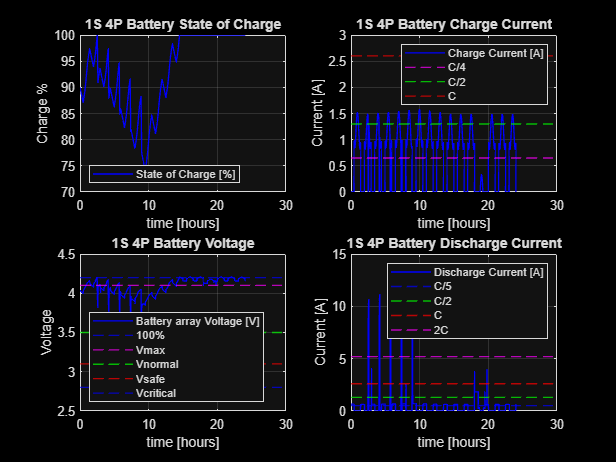


figure(8)
%set(gcf,'color','w');
set(gcf,'color','black');
    subplot(2,2,1)
        plot(time,SOC,'b','LineWidth',1)
        hold on;
        legend('State of Charge [%]')
        legend('Location','southwest')
        title('1S 4P Battery State of Charge')
        ylabel('Charge %')
        xlabel('time [hours]')
        grid on
subplot(2,2,2)
        plot(time,ibc,'b','LineWidth',1)
        hold on;
        yline(0.65, 'm--', 'LineWidth', 1);
        yline(1.3, 'g--', 'LineWidth', 1);
        yline(2.6, 'r--', 'LineWidth', 1);
        legend('Charge Current [A]','C/4','C/2','C')
        title('1S 4P Battery Charge Current')
        ylabel('Current [A]')
        xlabel('time [hours]')
        grid on

subplot(2,2,3)
        plot(time,Vbat,'b','LineWidth',1)
        hold on;
        yline(4.2, 'b--', 'LineWidth', 1);
        yline(4.1, 'm--', 'LineWidth', 1);
        yline(3.5, 'g--', 'LineWidth', 1);
        yline(3.1, 'r--', 'LineWidth', 1);
        yline(2.8, 'b--', 'LineWidth', 1);
        legend('Battery array Voltage [V]','100%','Vmax','Vnormal','Vsafe','Vcritical')
        legend('Location','southwest')
        title('1S 4P Battery Voltage')
        ylabel('Voltage')
        xlabel('time [hours]')
        grid on

subplot(2,2,4)
        plot(time,ibd,'b','LineWidth',1)
        yline(0.52, 'b--', 'LineWidth', 1);
        yline(1.3, 'g--', 'LineWidth', 1);
        yline(2.6, 'r--', 'LineWidth', 1);
        yline(5.2, 'm--', 'LineWidth', 1);
        hold on;
        legend('Discharge Current [A]','C/5','C/2','C','2C')
        title('1S 4P Battery Discharge Current')
        ylabel('Current [A]')
        xlabel('time [hours]')
        grid on